# State Signal Preperation File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 30/05/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

Set path to function folder

% Add /functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/dataprocessing/functions/'));

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Manipulation/',exportName);

Set Prepared data export path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

**Set Directories & Load Data**

Load Signal data

% use your default user path to create the filename and path
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'))
load 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
% load 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';


## 2. SIGNAL Data Manipulation

2.1 LAGS:

- CPI lag by 1 month

- Money supply lag by 1 month

- GDP lag by 3 months

- 'OECD' Leading indicator by 6 months

2.2 ROLLING RETURNS:

- SA Equity Momentum: Calculate 12 month rolling returns of JALSH 

2.3 SMOOTH:

Use a double decay method (Holt’s linear method) to smooth varaibles to reduce noise. 

2.4 COMPOSIT INDICES:

- Equity Risk Premium (USA - SA) 

- EQT_RISK_PREM =  (SPX-US003M)-(JALSH-JIBA3M)

### 2.1 Lag CPI and Money supply Indicators by 1 month to account for delay in information.

% varaibles to lag: SACPIYOY_Index & SAMYM3Y_Index
% Lag {'SACPIYOY_Index', 'SAMYM3Y_Index'} by 1 timestamp
lagged_SACPIYOY_Index = [NaN; SIG_aligned_dataTable.SACPIYOY_Index(1:end-1)];
lagged_SAMYM3Y_Index = [NaN; SIG_aligned_dataTable.SAMYM3Y_Index(1:end-1)];

GDP (3 mnth)

% Lag GDP {SAGDP_M_INTERPOLATED} by 3 months
lagged_SAGDP_Index = [NaN(3, 1); SIG_aligned_dataTable.SAGDP_M_INTERPOLATED(1:end-3)];

'OEZAKLAP_Index' (6 mnth)

% Lag GDP {SAGDP_M_INTERPOLATED} by 3 months
lagged_OEZAKLAP_Index = [NaN(6, 1); SIG_aligned_dataTable.OEZAKLAP_Index(1:end-6)];

### 2.2 Rolling Returns for SA Equity **Momentum** (12 month RR of JALSH)

% Divide each element in each column of x by the first element of that column
JALSH_TT = SIG_aligned_dataTable(:,'JALSHTR_Index');
% Can adjust the calmonths(x) arg to specify period of Rolling Returns.
JALSH_12M_RR = table2array(rollingreturns(JALSH_TT, 'Period', calmonths(12), 'EndOfMonth', true, 'Method','continuous'));

#### 2.2.1 Replace original vars with Adjusted 

% Add the lagged variables as columns to SIG_aligned_dataTable
SIG_aligned_dataTable.lagged_SACPIYOY_Index = lagged_SACPIYOY_Index;
SIG_aligned_dataTable.lagged_SAMYM3Y_Index = lagged_SAMYM3Y_Index;
SIG_aligned_dataTable.lagged_SAGDP_Index = lagged_SAGDP_Index;
SIG_aligned_dataTable.lagged_OEZAKLAP_Index = lagged_OEZAKLAP_Index;

% Rolling Returns as Momentum
SIG_aligned_dataTable.JALSH_12M_RR = JALSH_12M_RR

SIG_aligned_dataTable = 277×18 timetable
       Dates       JALSHTR_Index    OEZAKLAP_Index    SACPIYOY_Index    SAMYM3Y_Index    JPEIGLBL_Index    USDZAR_Curncy    NAPMPMI_Index    VIX_Index    SPX_Index    US0003M_Index    JIBA3M_Index    SAVIT40_Index    SAGDP_M_INTERPOLATED    lagged_SACPIYOY_Index    lagged_SAMYM3Y_Index    lagged_SAGDP_Index    lagged_OEZAKLAP_Index    JALSH_12M_RR
    ___________    _____________    ______________    ______________    _____________    ______________    _____________    _____________    _


% move original cols to end of TT
SIG_aligned_dataTable = movevars(SIG_aligned_dataTable,{'JALSHTR_Index','SACPIYOY_Index', 'SAMYM3Y_Index', 'SAGDP_M_INTERPOLATED','OEZAKLAP_Index'},'After',width(SIG_aligned_dataTable));

New timetable with only lagged values

SIG_prep_TT = SIG_aligned_dataTable(:, setdiff(SIG_aligned_dataTable.Properties.VariableNames, {'SACPIYOY_Index', 'SAMYM3Y_Index', 'SAGDP_M_INTERPOLATED','OEZAKLAP_Index'}));

#### **Remove NA:** 

We currently have 23 yrs of data, however, 15 yrs of historical data should suffice, therefore we can drop the dates prior to the initial existance of all indices:

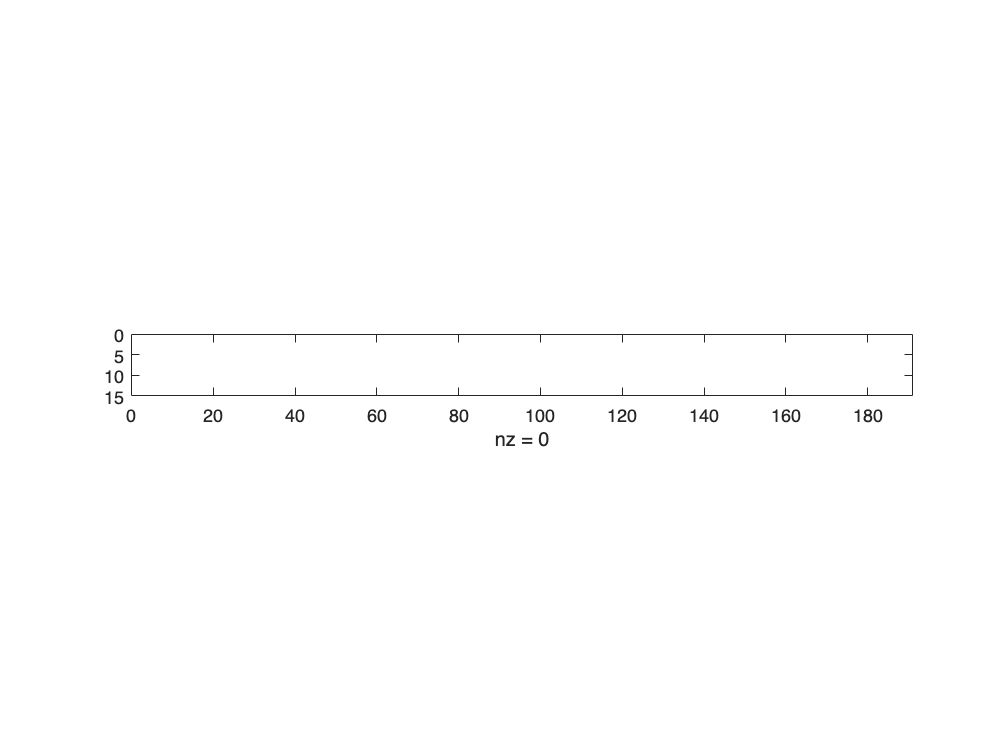

[countNans,idx] = max(sum(isnan(SIG_prep_TT{:,:}),1));
rmmissingProxy =  SIG_prep_TT.Properties.VariableNames{idx};
SIG_prep_TT = rmmissing(SIG_prep_TT,"DataVariables",rmmissingProxy);
spy(transpose(isnan(table2array(SIG_prep_TT))));

#### Plot adjsuted data

% rename the variables with underscores instead of spaces
SIG_PlotNames = strrep(SIG_prep_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
SIG_PlotNames = strrep(SIG_PlotNames, 'TR', '');

colors = [
    0 0.4470 0.7410;    % Blue
    0.8500 0.3250 0.0980;    % Orange
    0.9290 0.6940 0.1250;    % Yellow
    0.4940 0.1840 0.5560;    % Purple
    0.4660 0.6740 0.1880;    % Green
    0.3010 0.7450 0.9330;    % Light Blue
    0.6350 0.0780 0.1840;    % Red
    0 1 1;                  % Cyan
    1 0 1;                  % Magenta
    0.6039 0.8039 0.1961;   % Yellow-Green
    0.6350 0.0780 0.1840;   % Dark Red
    0.8 0.8 0.8;            % Light Gray
    0.3 0.3 0.3             % Dark Gray
];

figure;
plot(SIG_prep_TT.Dates, table2array(SIG_prep_TT), 'LineWidth', 1.5);
ylabel("Signals test_EWMA");
xlabel("Time");
title("Monthly State Variables");
legend(SIG_PlotNames, 'Location', 'northwest');
SIG_prep_TT_plot = gca;

% Assign colors to each line
for i = 1:numel(SIG_prep_TT_plot.Children)
    SIG_prep_TT_plot.Children(i).Color = colors(i, :);
end

hold off;

**Confim overlap of dates with BALFUN_log_diff data: **

BALFUN_log_diff runs from 31-Jul-2007 to 28-Feb-2023

SIG_prep_TT runs from 31-May-2007 to 28-Feb-2023

head(SIG_prep_TT)
tail(SIG_prep_TT)

### 2.3 Variable Smoothing using Meucci Double Decay

% Function to implement double decay or Holt's linear method
% Get the variable names from the timetable
varNames = SIG_prep_TT.Properties.VariableNames;

% Initialize the double decay or Holt's linear forecasted values
SIG_SMOOTHED_TT = timetable('RowTimes', SIG_prep_TT.Dates);

% Loop over each column/variable in the timetable
for i = 1:length(varNames)
    % Extract the data column
    data = SIG_prep_TT.(varNames{i});

    % Apply double decay or Holt's linear method
    z_signal = expDdecay(data, 3, 12);

    % Store the forecasted values in the new timetable
    SIG_SMOOTHED_TT.(varNames{i}) = z_signal;
end

Plot smoothed normalised data 

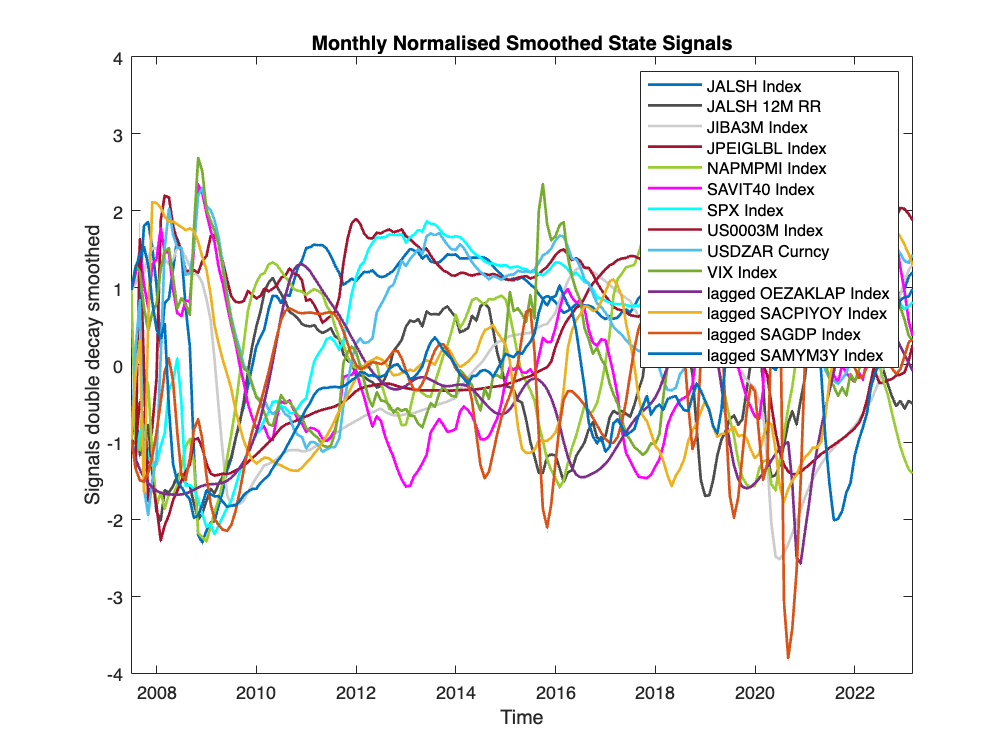

Index in position 1 exceeds array bounds. Index must not exceed 13.

% rename the variables with underscores instead of spaces
SIG_PlotNames = strrep(SIG_SMOOTHED_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
SIG_PlotNames = strrep(SIG_PlotNames, 'TR', '');

colors = [
    0 0.4470 0.7410;    % Blue
    0.8500 0.3250 0.0980;    % Orange
    0.9290 0.6940 0.1250;    % Yellow
    0.4940 0.1840 0.5560;    % Purple
    0.4660 0.6740 0.1880;    % Green
    0.3010 0.7450 0.9330;    % Light Blue
    0.6350 0.0780 0.1840;    % Red
    0 1 1;                  % Cyan
    1 0 1;                  % Magenta
    0.6039 0.8039 0.1961;   % Yellow-Green
    0.6350 0.0780 0.1840;   % Dark Red
    0.8 0.8 0.8;            % Light Gray
    0.3 0.3 0.3             % Dark Gray
];

figure;
plot(SIG_SMOOTHED_TT.Time, table2array(SIG_SMOOTHED_TT), 'LineWidth', 1.5);
ylabel("Signals double decay smoothed");
xlabel("Time");
title("Monthly Normalised Smoothed State Signals");
legend(SIG_PlotNames, 'Location', 'northeast');
SIG_prep_TT_plot = gca;

% Assign colors to each line
for i = 1:numel(SIG_prep_TT_plot.Children)
    SIG_prep_TT_plot.Children(i).Color = colors(i, :);
end


hold off;

### 2.4 Composit index for Equity Risk Premium (USA - SA) 

EQT_RISK_PREM =  (SPX-US003M)-(JALSH-JIBA3M)

EQT_RISK_PREM = (SIG_SMOOTHED_TT.SPX_Index-SIG_SMOOTHED_TT.US0003M_Index)-(SIG_SMOOTHED_TT.JALSHTR_Index-SIG_SMOOTHED_TT.JIBA3M_Index);
SIG_SMOOTHED_TT.EQT_RISK_PREM = EQT_RISK_PREM;

#### **SAVE Log Diff Returns Datasets:**

**TO DO: Use data_cleaning_001 to auto assign date range to file names (will code later)**

exportName = 'DATA-PROCESSED-SIG-SMTH-NORM-M-TTABLE-20070531-20230228.mat';
save(fullfile(dataExportpath,exportName),'SIG_SMOOTHED_TT');